clear all

Define function and its derivative

f=@(x)exp(-x.^2)

f = function_handle with value:
    @(x)exp(-x.^2)


df=@(x)-2.*x.*exp(-x.^2)

df = function_handle with value:
    @(x)-2.*x.*exp(-x.^2)


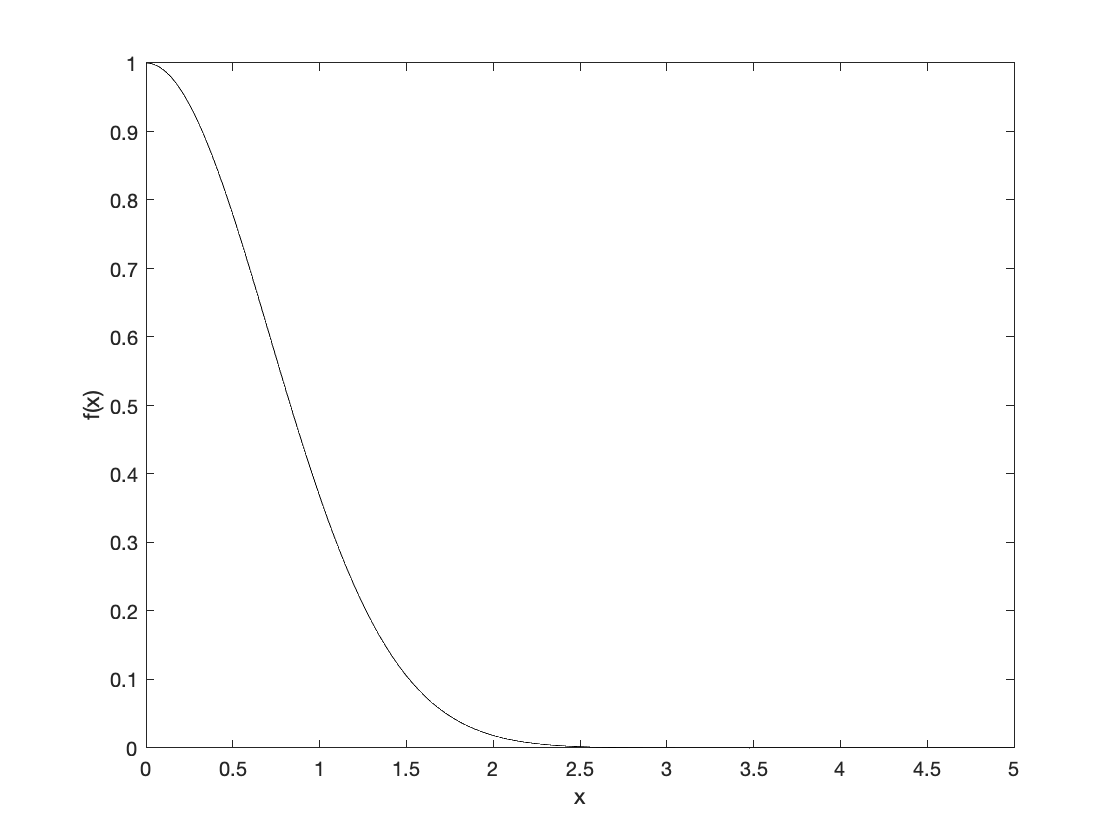

xveryfine=linspace(0,5,1000);

plot(xveryfine,f(xveryfine),'k-')
xlabel('x');ylabel('f(x)');

Generate equally spaced mesh for $x\in[0,5]$

n=60;
xi=linspace(0,5,n);
fi=f(xi);
Delta=xi(2)-xi(1);

Creating the derivative matrix $[D]$ and differentiate the function, i.e. calculate $\{f'\}=[D]\{f\}$.

b=zeros(n,1);
b(1)=-1;
b(end)=1;

a=-0.5*ones(n-1,1);
a(end)=-1;

c=0.5*ones(n-1,1);
c(1)=1;
Deriv=(diag(a,-1)+diag(b)+diag(c,1))/Delta;

% The derivative is  in the vector dfi. 

dfi=Deriv*fi';

Plot approximated derivative and exact analytical solution

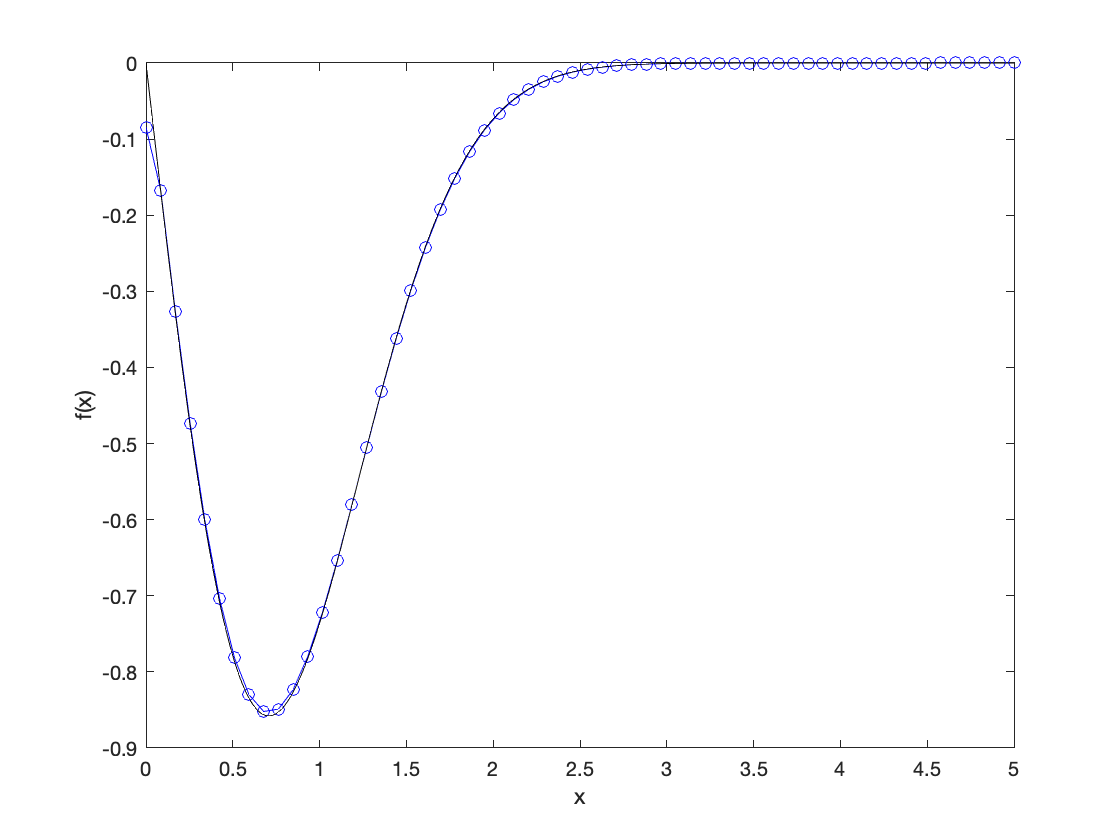

plot(xi,dfi,'bo-',xveryfine,df(xveryfine),'k-')
xlabel('x');ylabel('f(x)')

OK, the plot shows that the approximated derivative and the analytical function of the derivative falls on the same line.  Hence it seems like the derivative matrix is working properly.  But note that the derivative at $x=0$ is not well approximated.   This is because we are only using first order approximation of the derivative there (and also at $x=5$).  Higher order approximation (CDA) is used at the interior points. 

Now try to get $f_i=f(x_i)=\left\{f\right\}$ by solving $\left[D\right]\left\{f\right\}=\left\{df/dx\right\}$.  

linsolve(Deriv,dfi)

ans =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


This fails miserably!  How about we try with the \ operator in MATLAB

Deriv\dfi

ans =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


Fail as well! What is wrong??  We cannot solve because we have not specified the conditions at the boundaries. 

We should define boundary condition.  If not we cannot solve for a unique $f(x)$.  Modify the Deriv matrix and also dfi to specify the boundary condition $f(x=0)=1.0$

dfi=df(xi)

dfi =          0   -0.1683   -0.3294   -0.4766   -0.6044   -0.7082   -0.7853   -0.8345   -0.8563   -0.8526   -0.8265   -0.7819   -0.7231   -0.6546   -0.5807   -0.5052   -0.4313   -0.3616   -0.2978   -0.2410   -0.1917   -0.1499   -0.1153   -0.0873   -0.0650   -0.0476   -0.0343   -0.0244   -0.0170   -0.0117   -0.0079   -0.0053   -0.0035   -0.0022   -0.0014   -0.0009   -0.0006   -0.0003   -0.0002   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


Deriv(1,1)=1;Deriv(1,2:end)=0.0;dfi(1)=1.0;

Now try solving for $\left\{f\right\}$

fnumeric=linsolve(Deriv,dfi');

Now plot the solution and compare with the "real" $f(x)=e^{-x^2}$.

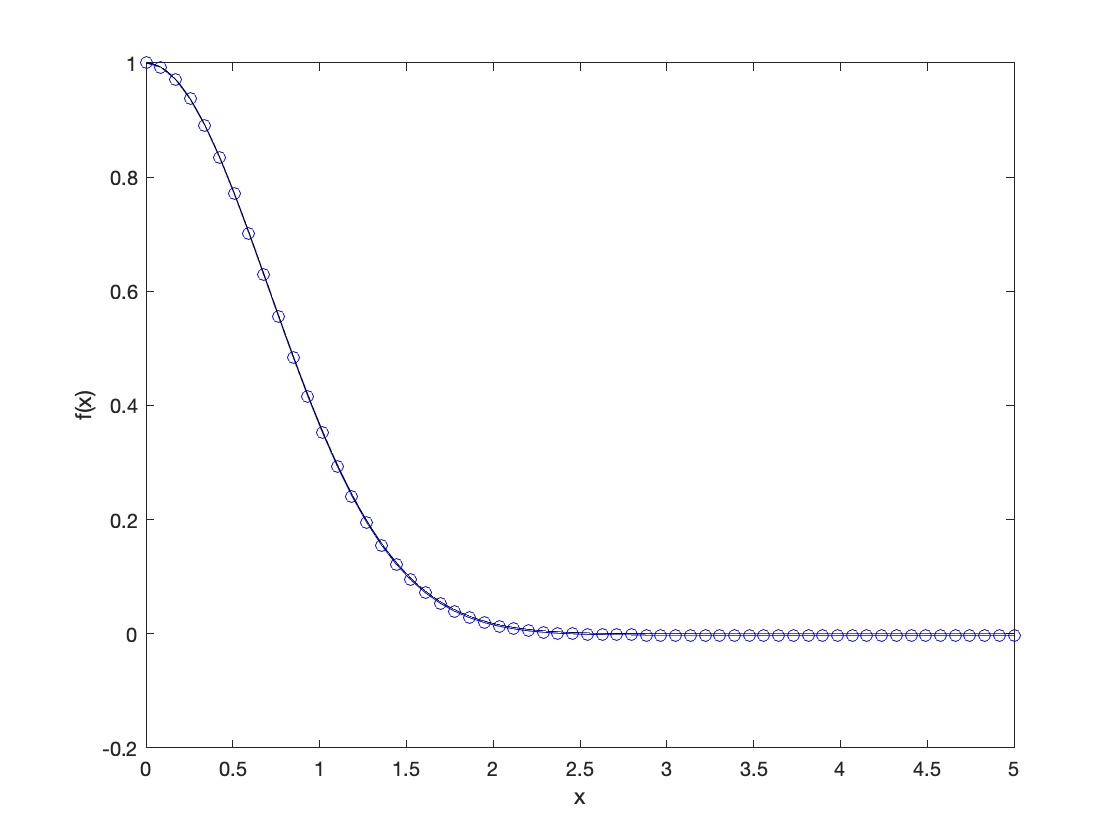

plot(xi,fnumeric,'bo-',xveryfine,f(xveryfine),'k-')
xlabel('x');ylabel('f(x)')

Or we put everything we know on to the RHS

temp=dfi(2:end)';
temp(1)=temp(1)+1./(2*Delta);
sol=Deriv(2:end,2:end)\temp;

Append element to first array and plot

sol=[1; sol];
plot(xi,sol,'bo-',xveryfine,f(xveryfine),'k-')
xlabel('x');ylabel('f(x)')